%is low rank aprroximation correct terminology?
%try useing GPU arrays
%load("ignitionCropped.mat");
clear all; close all; clc;
%clearvars;

%get data
%load('C:\Users\satur\OneDrive\Documents\MATLAB\data_tsb.mat');
load('data_tsb.mat');
%load('ignitionCropped.mat'); % 4d video
%load('Grey_Ignition_video.mat'); % also 4d video

%{
U_Z0_VER_Run1: longitudinal velocity
V_Z0_VER_Run1: vertical velocity
axeX_Z0: x-coordinates of data points
axeY_Z0: y-coordinates of data points
Nt: number of snapshots
%}



% Reshape into meshgrid standard (not my code)
% U_raw & V_raw are of the from S(i,j,k)
% where i is the y-position in the field of view
% j is the x-position
% k is the snapshot index
% One snapshot was taken every 1.1 milliseconds (fs = 900 Hz).
X_raw = axeX_Z0';
Y_raw = flipud(axeY_Z0-axeY_Z0(1,1))';
U_raw = permute(U_Z0_VER_Run1, [2,1,3]);
V_raw = permute(V_Z0_VER_Run1, [2,1,3]);

% Undersample every 3 points (x and y change; t stays the same) (not my code)
% because my computer is not very fast
X = X_raw(1:3:end,1:3:end);
Y = Y_raw(1:3:end,1:3:end);
SU = U_raw(1:3:end,1:3:end,1:1:end); %SU longitudinal velocity snapshot matrix
SV = V_raw(1:3:end,1:3:end,:); %SV verticle velocity snapshot matrix


%for videos
%videoFrames = double(videoFrames(1:5:end,1:5:end,:,:)); %undersample by 5 %5 rund fine %range 0-255
%videoFrames = videoFrames(:,:,:,end:-1:1); % for running dmd backwards
%{
%take one colour from rgb videos to make data 3D (used diring development)
size(videoFrames)%for debugging
redVideoFrames = squeeze(videoFrames(:,:,1,:));
ndims(redVideoFrames); %for debugging
%}


## Visualization Options Configuration

visualizeTimeDynamics = true

visualizeTimeDynamics = logical
   1


visualizeModes = true

visualizeModes = logical
   1


visualizeReconstruction = false

visualizeReconstruction = logical
   0


seperateBackground = false

seperateBackground = logical
   0


## Dynamic Mode Decomposition


%use _ modes ->
% for bottle video: 4 modes is sufficient -> probably this means it's broken, 10 is sufficient. 30 is inditinguishable.
%for tsb -> 
% try 1, 4, 7, and 10 modes
% delta t is 1.1 miliseconds

dmd = DynamicModeDecomposer(SU, "rank",-1, "delta_t",1.1, "backgroundSeperation",seperateBackground);


## Visualize Time Dynamics

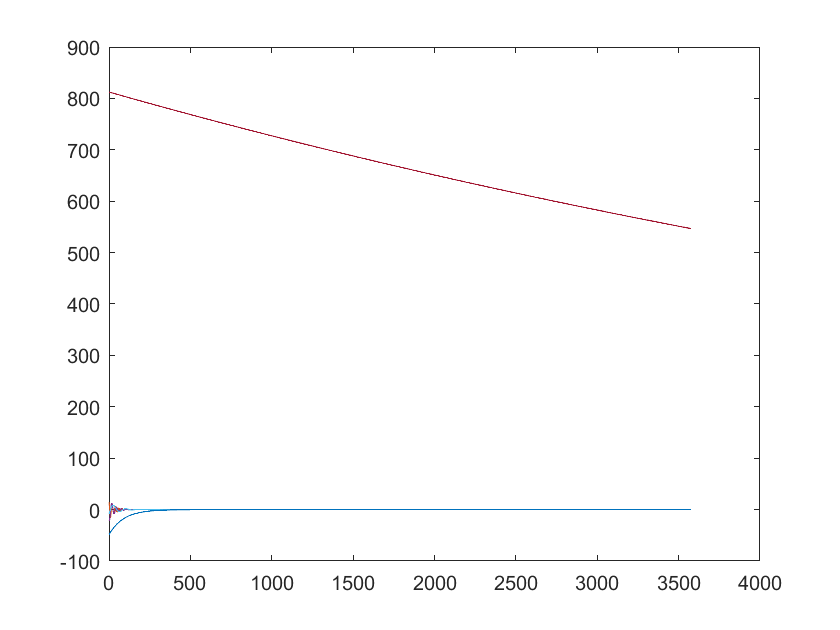

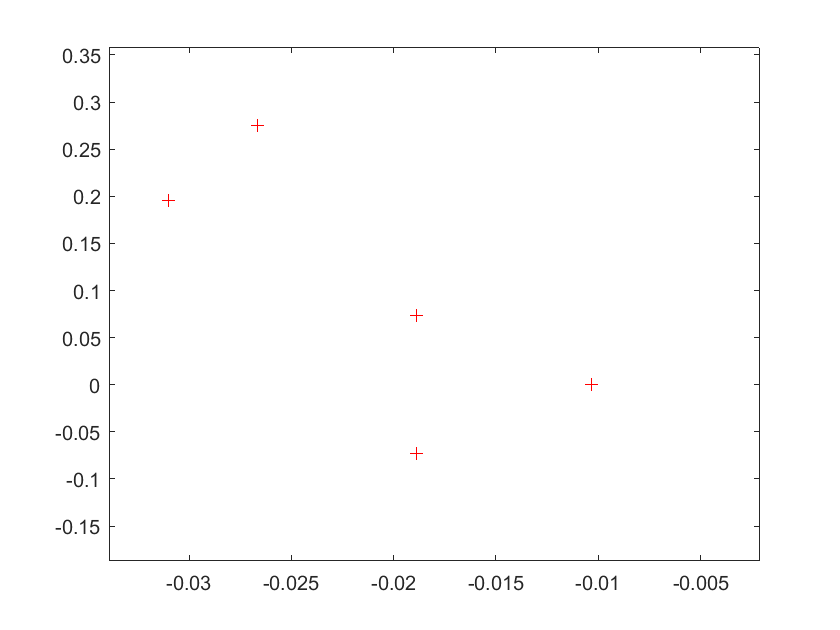

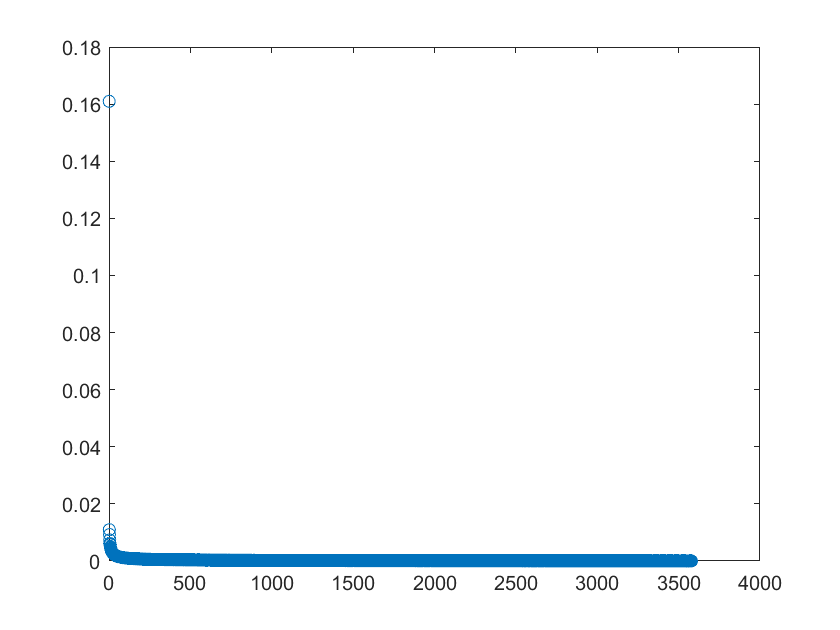

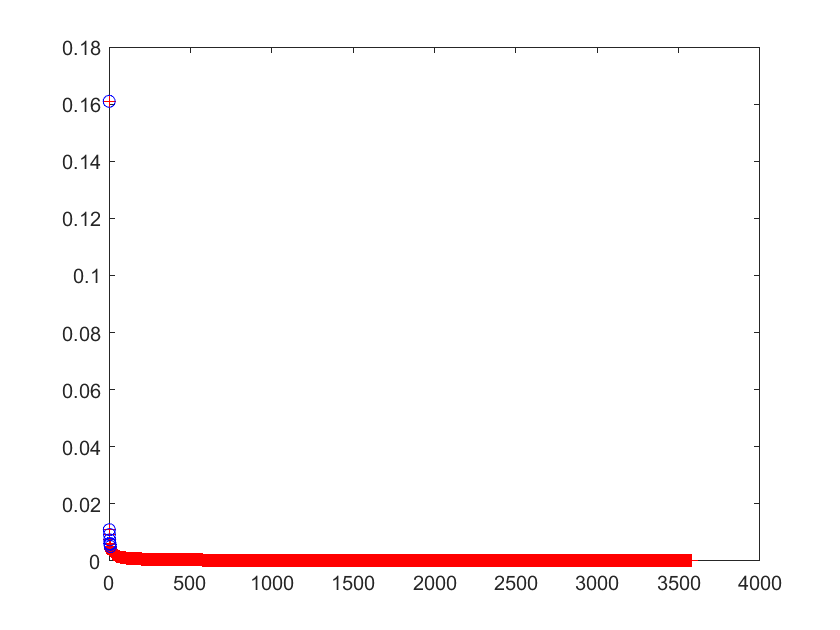

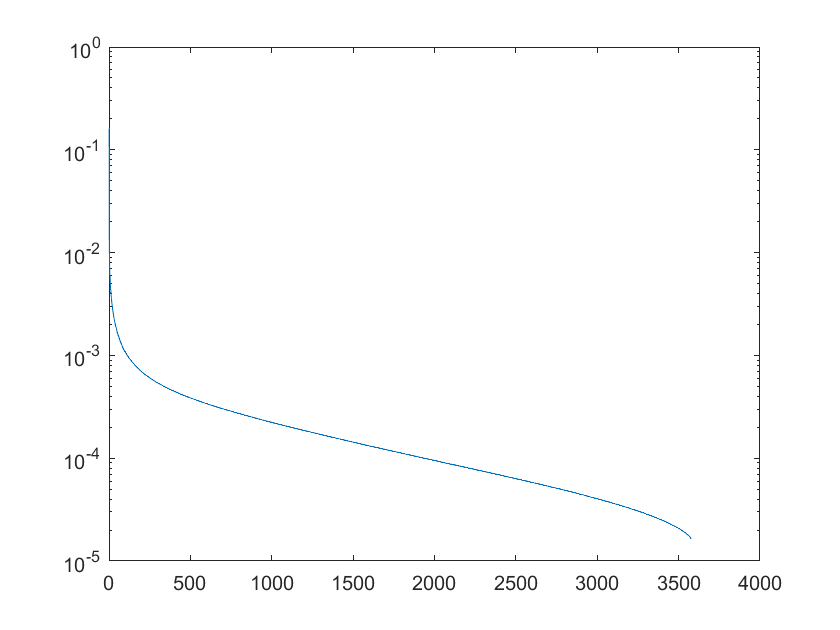

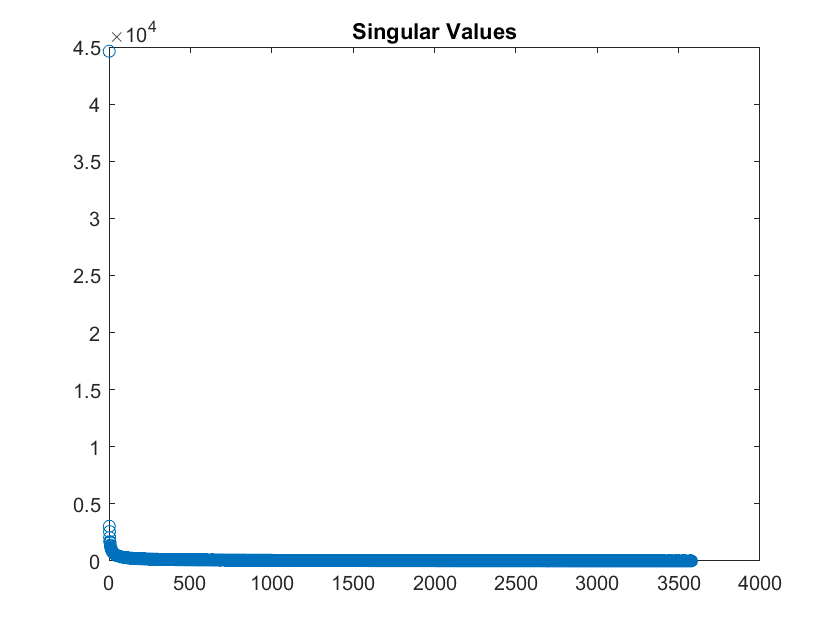

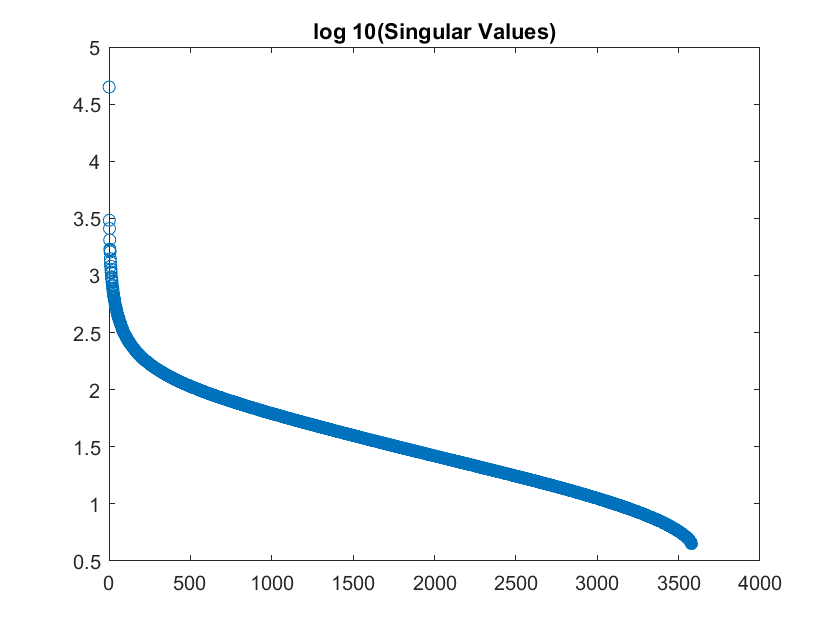

if visualizeTimeDynamics
    % plot time dynamics of each mode
    figure
    plot(real(dmd.timeDynamics)')

    % plot eigen values vs frequency
    figure
    plot(dmd.continuousTimeEigenValues,'+r')
    
    % plot singular values
    figure;
    plot(dmd.singularValues/sum(dmd.singularValues),'o');
    
    figure;
    plot(dmd.singularValues/sum(dmd.singularValues),'r+');
    hold on
    plot(dmd.truncatedSingularValues/sum(dmd.singularValues),'bo');
    
    figure
    semilogy(dmd.singularValues./sum(dmd.singularValues));
    
    figure
    plot(dmd.singularValues,'o'), title('Singular Values');
    
    figure
    plot(log10(dmd.singularValues),'o'), title('log 10(Singular Values)');
end

## Visualize Modes

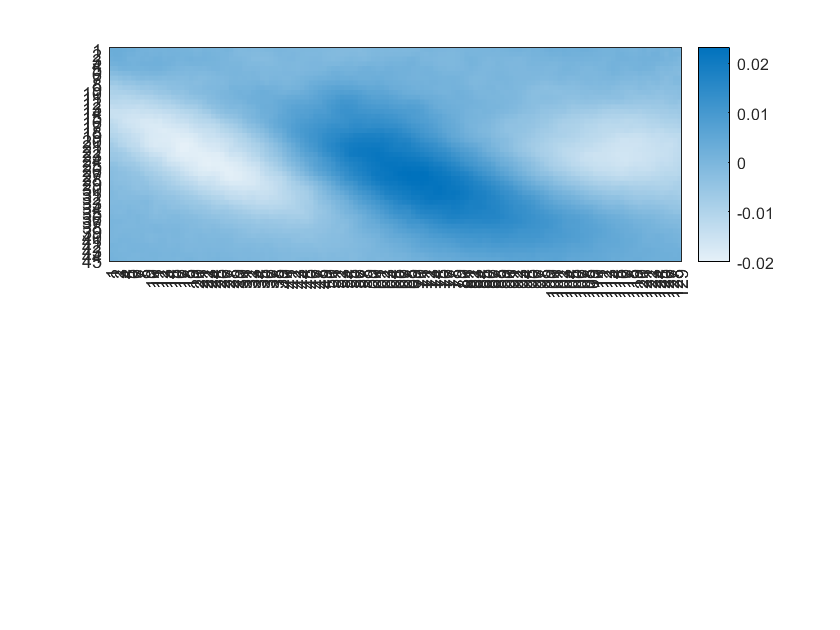

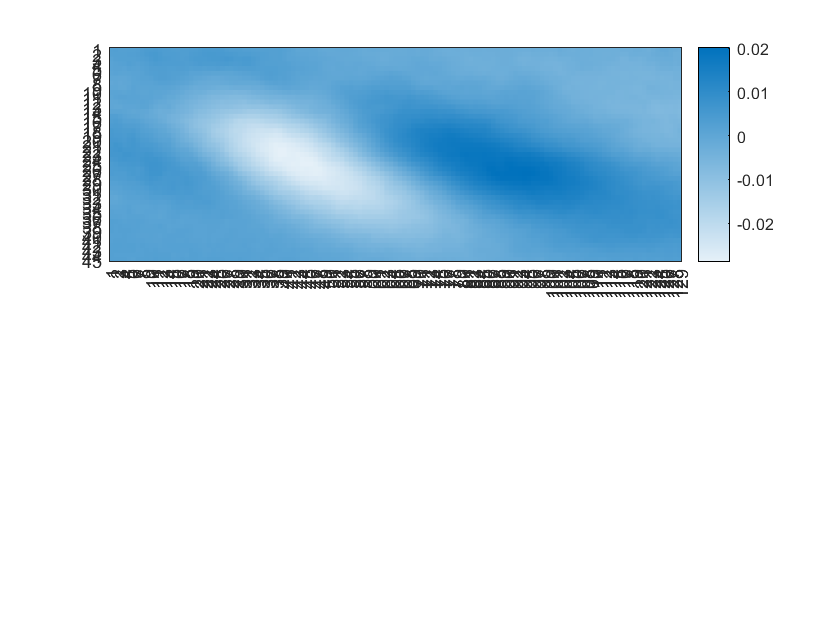

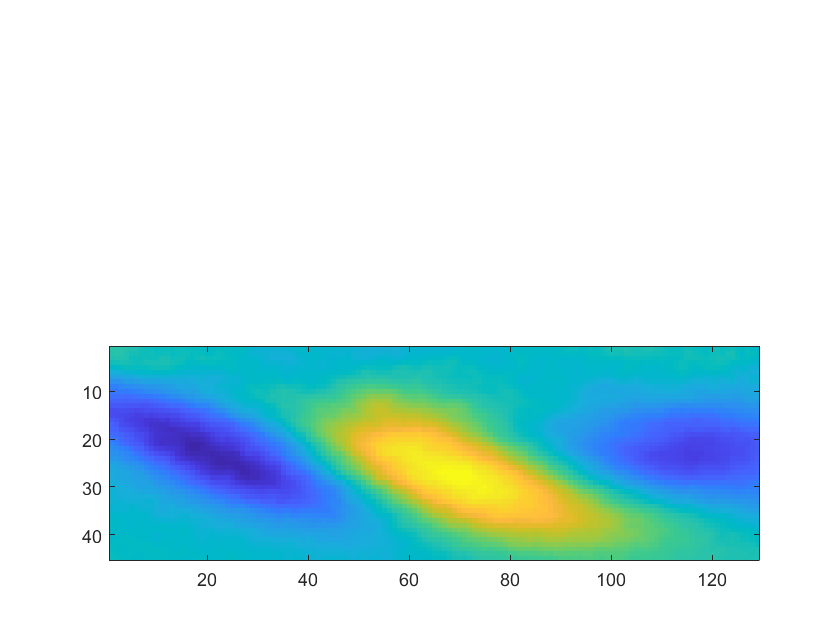

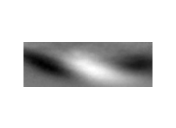

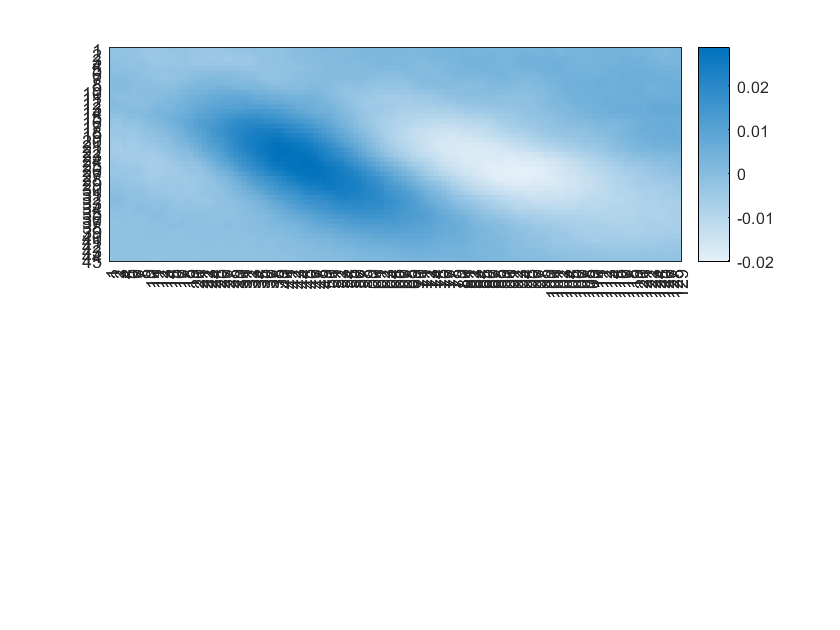

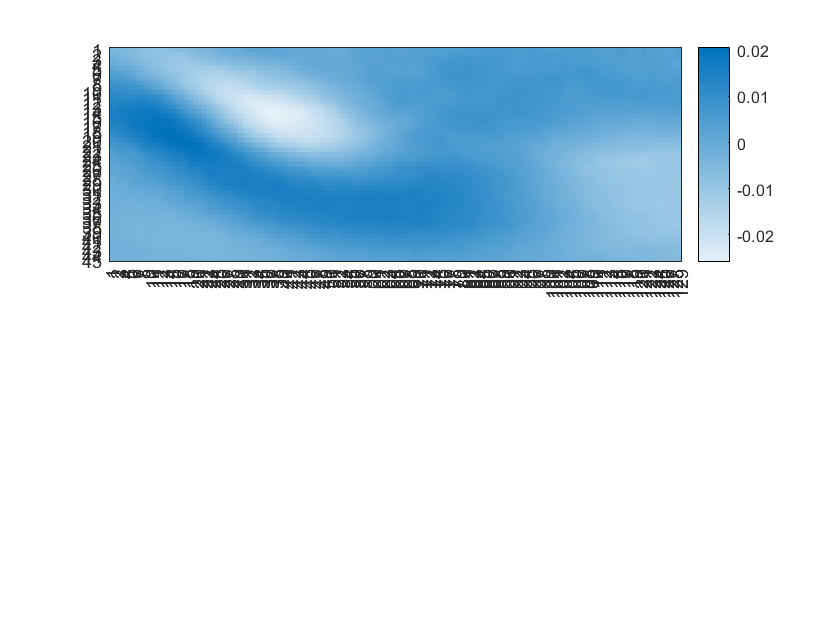

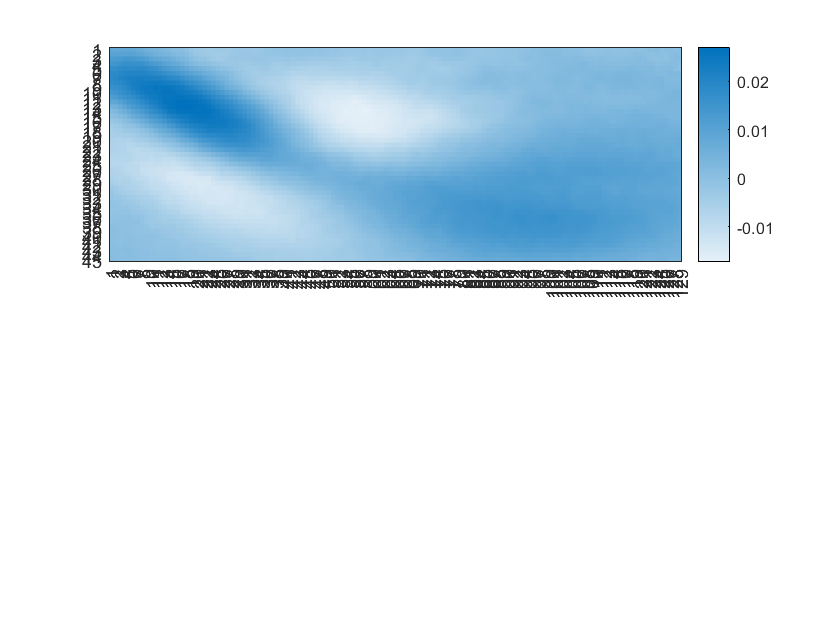

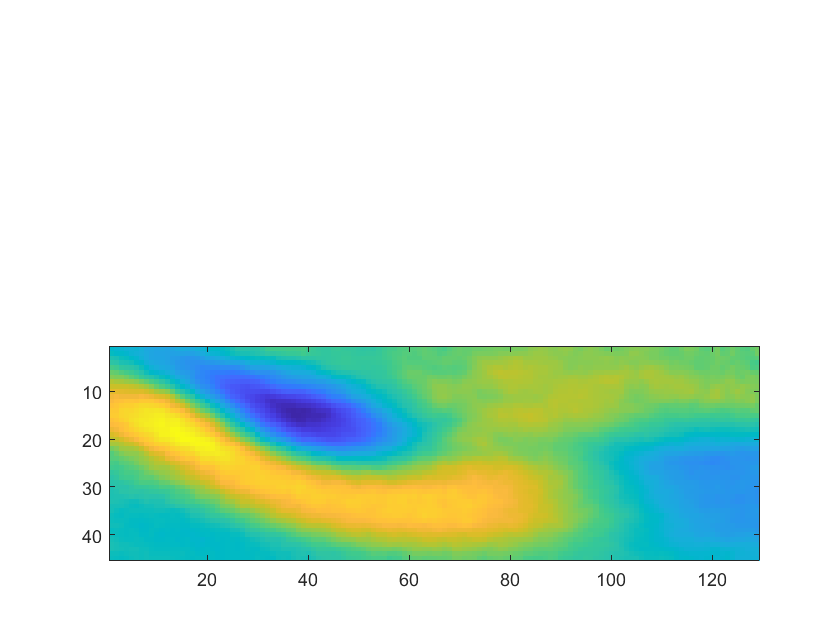

if visualizeModes
    modes = dmd.getModes(-1); %rank of -1 means use full rank

    % size(modes) for debugging

    %TODO visualization with methods


    if ndims(modes) == 3 %3D data
        for i = 1:size(modes,3)
            drawnow; %this aloows fo termination of ececution of program
            %mode = modes(:,:,i)
            %heatmap(real(mode)), grid off;
            figure
            subplot(2,1,1);
            heatmap(real(modes(:,:,i)),"YData",1:size(SU,1),"XData",1:size(SU,2)), grid off;

            figure
            subplot(2,1,1);
            heatmap(imag(modes(:,:,i)),"YData",1:size(SU,1),"XData",1:size(SU,2)), grid off;
            figure
            
            %figure
            subplot(2,1,2);
            imagesc(real(modes(:,:,i))); % plot vorticity field
            %load CCcool.mat
            %colormap(CC); % use custom colormap

            figure
            %subplot(1,2,2);
            %subimage(uint8(real(modes(:,:,i))))
            imshow(mat2gray(real(modes(:,:,i))));
        end
    elseif ndims(modes) == 4 %4D data
        %rescale modes a a whole such that the max and min values are more
        %representative? not sure that that it true for modes
        rmodes = im2uint8(rescale(real(modes)));


        for i = 1:size(modes,4)
            drawnow; %this aloows fo termination of ececution of program
            %mode = modes(:,:,i)
            %heatmap(real(mode)), grid off;

            figure

            for j = 1:3
                subplot(1,3,j);
                imshow(mat2gray(real(modes(:,:,j,i))));
            end

            figure
            for j = 1:3
                subplot(1,3,j);
                imshow(mat2gray(imag(modes(:,:,j,i))));
            end
            
            %         figure
            %         subplot(1,2,1);
            %
            %         %heatmap(real(modes(:,:,:,i)),"YData",1:size(videoFrames,1),"XData",1:size(videoFrames,2)), grid off;
            %         %figure
            %         subplot(1,2,2);
            %         subimage(uint8(squeeze(real(modes(:,:,:,i))))); % plot vorticity field %todo wtf
            %
            
            
            %{
            colourArray = real(modes(:,:,:,i)); % creats a 4d array of real doubles
            %colourArray = uint8(colourArray); % converts to integers
            %colourArray = squeeze(colourArray) % removes the excess dimention it is now 3d

            %         figure
            %         imagesc(colourArray);


            figure
            %manualy try to scale the values
            maxVal = max(colourArray(:,:,:));
            minVal = min(colourArray(:,:,:));


            %old recontruction
            colourArray = uint8(255*double(double(colourArray(:,:,:) - minVal) ./ double( maxVal - minVal)));
            subplot(1,3,1);
            image(colourArray);
            %}
            
            
            %{
            %combined rescaled reconstruction
            subplot(1,3,2);
            image(rmodes(:,:,:,i));
            %}
            
            figure
            %{
            subplot(1,3,1);
            myimage = im2uint8(rescale(real(modes(:,:,:,i)))); axis equal;
            image(myimage);
            hold on;
            myimage = im2uint8(rescale(imag(modes(:,:,:,i)))); axis equal;
            image(myimage);
            %}
            
            %visualize imaginary part of mode
            subplot(1,3,2);
            myimage = im2uint8(rescale(imag(modes(:,:,:,i)))); axis equal;
            image(myimage), axis equal;
    
            
            %visualize real m=par of mode
            %good reconstruction
            subplot(1,3,3);
            myimage = im2uint8(rescale(real(modes(:,:,:,i)))); axis equal;
            image(myimage), axis equal;

        end
    else
        throw(MException("datamatrix not regonised as having 3 or 4 dimentions"));
    end

end

## visualize reconstruction

if visualizeReconstruction
    
    %dmd.modes * exp(dmd.continuousTimeEigenValues*[1:60]) * dmd.b;

    %movie = zeros(size(dmd.reconstructedDataMatrix(),ndims(dmd.reconstructedDataMatrix)));


    %rescaledReconstruction = im2double(rescale(dmd.reconstructedDataMatrix)); %this does not look good
    %rescaledOriginal =  im2double(rescale(videoFrames));

    %[Phi, omega, lambda, b, Xdmd] = DMD(dmd.snapshotMatrix(:,1:end-1), dmd.snapshotMatrix(:,2:end),30,1/900);

    %reconstructedData = dmd.snapshots2data(Xdmd,[dmd.dataDimentions(1),dmd.dataDimentions(2),dmd.dataDimentions(3)-1]);

    reconstructedData = dmd.reconstructedDataMatrix;
    if seperateBackground
        forgroundData = dmd.reconstructedForgroundData;
        backgroundData = dmd.reconstructedBackgroundData;
    end


    %removeing mean is fun but not helpful right now
    %meanDataMatrix = dmd.snapshots2data(dmd.meanMatrix,dmd.dataDimentions);
    % reconstructedData = reconstructedData - meanDataMatrix(:,:,:,1:end-1);

    %removeing specific mode currently not working
    % reconstructedData = reconstructedData - modes(:,:,:,24) .* dmd.timeDynamics(24,:)

    frames = 100 % dont visualize more than _ frames
    
    numberOfSnapshots = size(dmd.reconstructedDataMatrix,ndims(dmd.reconstructedDataMatrix));
    stepsize = max(1,fix(numberOfSnapshots/frames)); % integer division or 1 if answer is less than 1
    
    for t = (1:stepsize:numberOfSnapshots)
    %for t =(1:min(frames,size(dmd.reconstructedDataMatrix,ndims(dmd.reconstructedDataMatrix))))
    % old for loop iterataed for until frams now we undersanple 
        drawnow; %this aloows fo termination of ececution of program
        if numel (dmd.dataDimentions) == 3
            %visualize recontruction
            figure
            imshow(mat2gray(real(reconstructedData(:,:,t))));
            %visualize original
            figure
            imshow(mat2gray(real(SU(:,:,t))));

            %visualize both
            figure
            subplot(2,1,1)
            imshow(mat2gray(real(reconstructedData(:,:,t))));
            subplot(2,1,2)
            imshow(mat2gray(real(SU(:,:,t))));
            
            figure
            imshowpair(mat2gray(real(reconstructedData(:,:,t))),mat2gray(real(SU(:,:,t))),'diff');

        elseif numel(dmd.dataDimentions) == 4
            figure
            for j = 1:3
                subplot(1,3,j);
                imshow(mat2gray(real(reconstructedData(:,:,j,t))));
            end
            
            if seperateBackground
                figure
                for j = 1:3
                    subplot(1,3,j);
                    imshow(mat2gray(real(forgroundData(:,:,j,t))));
                end

                figure
                for j = 1:3
                    subplot(1,3,j);
                    imshow(mat2gray(real(backgroundData(:,:,j,t))));
                end
            end
            
            figure
            for j = 1:3
                subplot(1,3,j);
                imshow(mat2gray(real(videoFrames(:,:,j,t))));
            end

            %reconstruction with by frame rescaleing
            figure
            %draw reconstruction on left
            subplot(1,3,1);
            image(im2uint8(rescale(reconstructedData(:,:,:,t)))); axis equal;
            
            %draw forground in center
            if seperateBackground
                subplot(1,3,2);
                image(im2uint8(rescale(reconstructedData(:,:,:,t)))); axis equal;
            end
            
            %draw original on right
            subplot(1,3,3);
            image(im2uint8(rescale(videoFrames(:,:,:,t)))); axis equal; % unnesseary as vid frames are already uint 8

            %i previously used im2double - which would have done nothing

            %{
        %visualization test revealed that frame by frame rescaleing of
        reconstruction is the most authentic recontruction technique
        %alt recontruction with original video (not recscaled by frame)
        figure
        %draw alternate reconstruction in middle
        subplot(1,3,2);
        image(rescaledReconstruction(:,:,:,t))
        %draw alternate original on right
        subplot(1,3,3);
        image(rescaledOriginal(:,:,:,t))
        %draw raw orginial on left
        subplot(1,3,1);
        image(uint8(videoFrames(:,:,:,t)))
            %}

            %TODO: make nice astheticly apealing visulaization

            %foo =  getframe(gcf);

        else
            throw(MException("datamatrix not regonised as having 3 or 4 dimentions"));
        end

        M(t) = getframe(gcf);
    end


## Save Video


moviePlayer = VideoWriter('DMD_RBG_Ignition','MPEG-4');
moviePlayer.FrameRate = 20;
open(moviePlayer);
writeVideo(moviePlayer,M);
close(moviePlayer);

end %end visualize reconstruction

%heatmap(mode1), grid off;
%[modes, eigneValues] = dmd.decompose();

%get eigen thingies from dmd

%data = dmd.snapshots2data(modes(:,1),[45,129,1]);
%heatmap(real(data)),grid off

% [Phi, omega, lambda, b, Xdmd] = DMD(dmd.snapshotMatrix(:,1:end-1), dmd.snapshotMatrix(:,2:end),30,1/900)
% 
% dmd.snapshots2data(Xdmd,[dmd.dataDimentions(1),dmd.dataDimentions(2),dmd.dataDimentions(3)-1]);




%heatmap(real(Xdmd)), grid off
%surfl(real(Xdmd')), shading interp; colormap(gray ); view (-20,60);




%dmd.snapshots2data(Xdmd,dmd.dataDimentions);



%not my code




function [Phi ,omega ,lambda ,b,Xdmd] = DMD(X1,X2,r,dt)
% function [Phi ,omega ,lambda ,b,Xdmd ] = DMD(X1,X2,r,dt)
% Computes the Dynamic Mode Decomposition of X1, X2
%
% INPUTS:
% X1 = X, data matrix
% X2 = X’, shifted data matrix
% Columns of X1 and X2 are state snapshots
% r = target rank of SVD
% dt = time step advancing X1 to X2 (X to X’)
%
% OUTPUTS:
% Phi , the DMD modes
% omega , the continuous-time DMD eigenvalues
% lambda , the discrete -time DMD eigenvalues
% b, a vector of magnitudes of modes Phi
% Xdmd, the data matrix reconstructed by Phi , omega , b
%% DMD
[U, S, V] = svd(X1, 'econ');
r = min(r, size(U,2));
U_r = U(:, 1:r); % truncate to rank-r
S_r = S(1:r, 1:r);
V_r = V(:, 1:r);
Atilde = U_r' * X2 * V_r / S_r; % low -rank dynamics
[W_r , D] = eig(Atilde);
Phi = X2 * V_r / S_r * W_r; % DMD modes
lambda = diag(D); % discrete -time eigenvalues
omega = log(lambda)/dt; % continuous-time eigenvalues
%% Compute DMD mode amplitudes b
x1 = X1(:, 1);
b = Phi\x1;
%% DMD reconstruction
mm1 = size(X1, 2); % mm1 = m - 1
time_dynamics = zeros(r, mm1);
t = (0:mm1 -1)*dt; % time vector
for iter = 1:mm1
    time_dynamics (:,iter )=(b.*exp(omega*t(iter )));
end
Xdmd = Phi * time_dynamics;
end

%my code

% function dataMatrix = snap2data(snapshotMatrix)
%     dimentionality = size(dataDimentions,2);
%     
%     %undo transformations done in data2snapshots
%     if (dimentionality == 3) % data is a 3d matrix
%         dataMatrix = permute(reshape(snapshotMatrix,dataDimentions(3),dataDimentions(2),[]),[3,2,1]);
%     elseif (dimentionality == 4) % data is a 4d matrix
%         dataMatrix = ipermute(reshape(snapshotMatrix,dataDimentions(4),dataDimentions(1),dataDimentions(2),[]),[4,1,2,3]);
%     else
%         throw(MException("data matrix not regonised as having 3 or 4 dimentions"));
%     end
% end

function colourArray = data2rgb(data)
    colourArray = real(data(:,:,:));
    colourArray = removeOutliers(colourArray);
    %colourArray = rmoutliers(colourArray);
    maxVal = max(colourArray(:,:,:));
    minVal = min(colourArray(:,:,:));
    colourArray = uint8(255*double(double(colourArray(:,:,:) - minVal) ./ double( maxVal - minVal)));
end

function outlierFreeData = removeOutliers(rgbData)
    dataR = rgbData(:,:,1);
    dataG = rgbData(:,:,2);
    dataB = rgbData(:,:,3);
    
    %find ourliers
    [~, rRemoved] = rmoutliers(dataR,2);
    [~, bRemoved] = rmoutliers(dataG,2);
    [~, gRemoved] = rmoutliers(dataB,2);
    toRemove = bitor(bitor(rRemoved,gRemoved),bRemoved);
    
    %for debugging
    sprintf('outliersRemoved = %i',sum(toRemove));
    
    removalIndecies = find(toRemove);
    
    %remove outlires
    
    rgbData(:,[removalIndecies],:) = [];
%     for i = length(toRemove):1
%         if toRemove(i) == 1
%             rgbData(i,:,:) = [];
%         end
%     end
    
    outlierFreeData = rgbData;
end


%{
%original method i used
%gives distorted results (weird columns of different colours)
function colourArray = data2rgb(data)
    colourArray = real(data(:,:,:));
    maxVal = max(colourArray(:,:,:));
    minVal = min(colourArray(:,:,:));
    colourArray = uint8(255*double(double(colourArray(:,:,:) - minVal) ./ double( maxVal - minVal)));
end
%}


% function colourArray = data2rgb(data)
%     colourArray = real(data(:,:,:));
%     
%     if isa(colourArray,'double')
%         colourArray = (data(:,:,:) + 1) ./ 2;
%     else
%         return;
%     end
% end

